clear;
load data.mat;
load output.mat;

m = size(x, 1);
x = [ones(m, 1) x];
n = size(x, 2);
alpha = 0.001;
theta = rand(n, 1);
theta_old = theta;
iters = 10;

thetas = [];
thetas = [thetas; theta'];
for i = 1:iters
    theta = theta + alpha*(1/m)*(x'*(y - (x*theta)));
    thetas = [thetas; theta'];
end

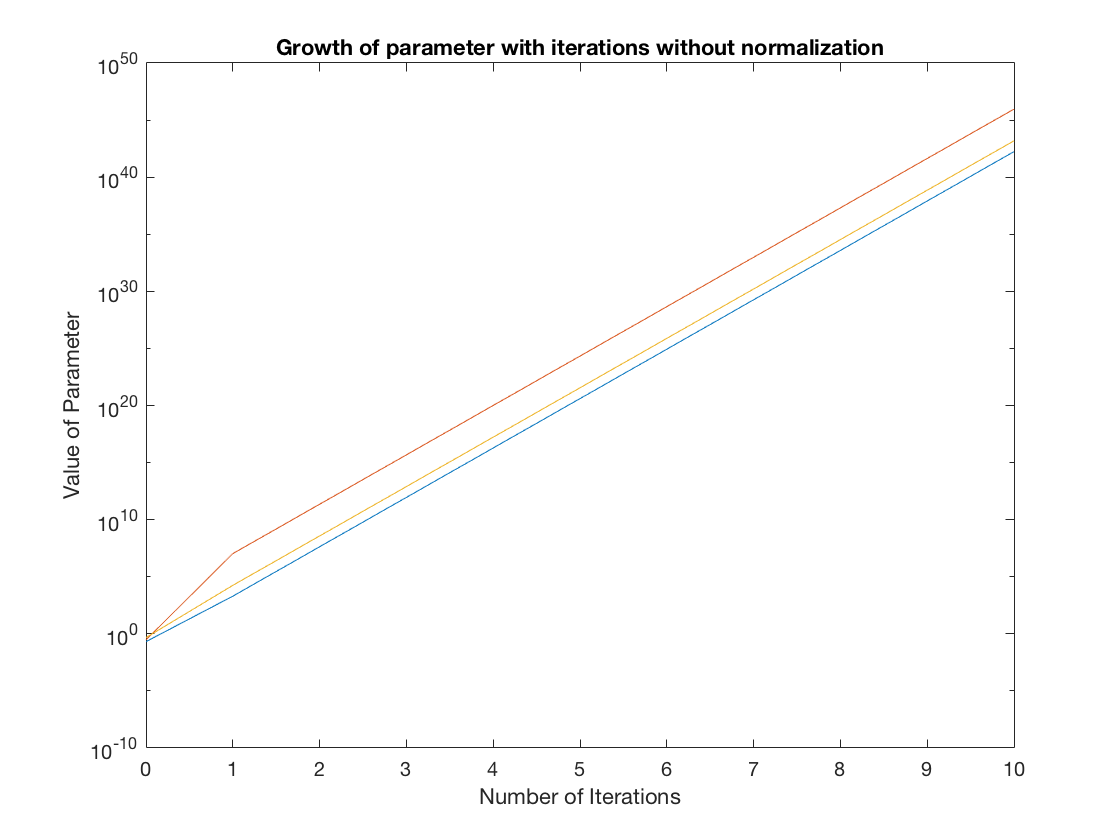

iterations = (0:iters)';
figure;
semilogy(iterations, abs(thetas(:, 1)));
hold on;
semilogy(iterations, abs(thetas(:, 2)));
semilogy(iterations, abs(thetas(:, 3)));
ylabel('Value of Parameter');
xlabel('Number of Iterations');
title('Growth of parameter with iterations without normalization');

iters = 1000;
for i = 2:n
    x(:, i) = (x(:, i) - mean(x(:, i)))/std(x(:, i));
end
y = (y - mean(y))/std(y);

theta = theta_old;

err_regression = [];
theta_regression = [];

err_regression = [err_regression; sum((y-x*theta).^2)];
theta_regression = [theta_regression; theta'];

for i = 1:iters
    theta = theta + alpha*(1/m)*(x'*(y - (x*theta)));
    err_regression = [err_regression; sum((y-x*theta).^2)];
    theta_regression = [theta_regression; theta'];
end

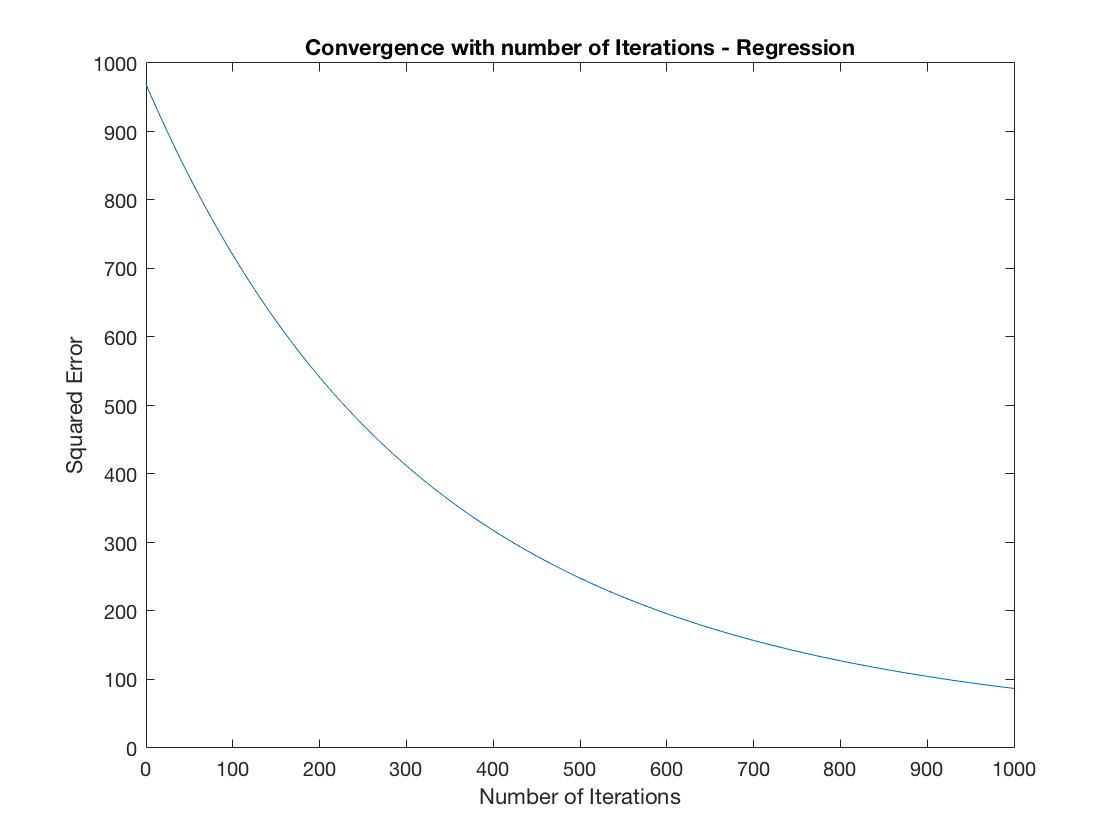

iterations = (0:iters)';
figure;
plot(iterations, err_regression);
hold on;
xlabel('Number of Iterations');
ylabel('Squared Error');
title('Convergence with number of Iterations - Regression');

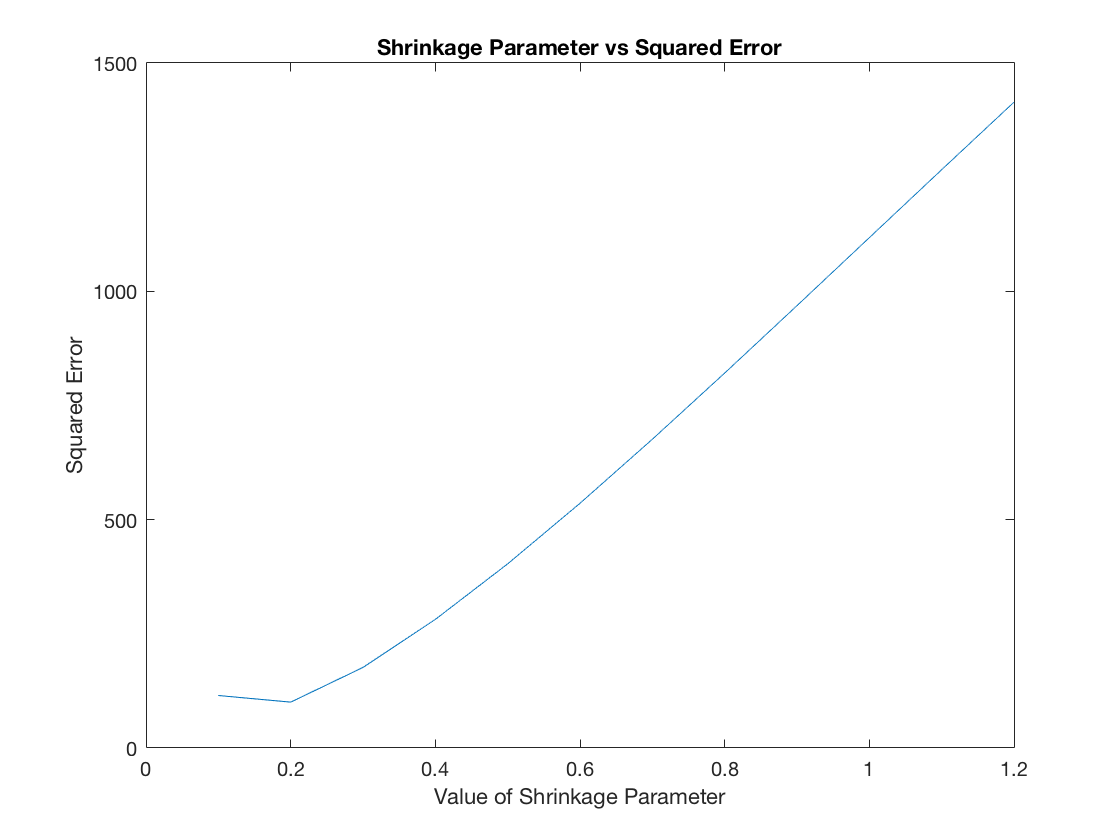

theta = theta_old;


ldas = 0.1:0.1:1.2;
lda_errs = [];


for lda=ldas
    for i = 1:iters
        theta = theta + alpha*(1/m)*(x'*(y - (x*theta))) - alpha*lda*theta;
    end
    lda_errs = [lda_errs; sum((y-x*theta).^2)];
end

figure;
plot(ldas, lda_errs);
xlabel('Value of Shrinkage Parameter')
ylabel('Squared Error')
title('Shrinkage Parameter vs Squared Error')


[m, i] = min(lda_errs);
lda = ldas(i);

theta = theta_old;


theta_ridge = [];
err_ridge = [];

theta_ridge = [theta_ridge; theta'];
err_ridge = [err_ridge; sum((y-x*theta).^2)];

for i = 1:iters
    theta = theta + alpha*(1/m)*(x'*(y - (x*theta))) - alpha*lda*theta;
    theta_ridge = [theta_ridge; theta'];
    err_ridge = [err_ridge; sum((y-x*theta).^2)];
end

theta_bar_plot = [theta_ridge(size(theta_ridge, 1), :)' theta_regression(size(theta_regression, 1), :)']

theta_bar_plot =     0.0000    0.0764
    0.5565    0.4013
    0.4425    0.5678


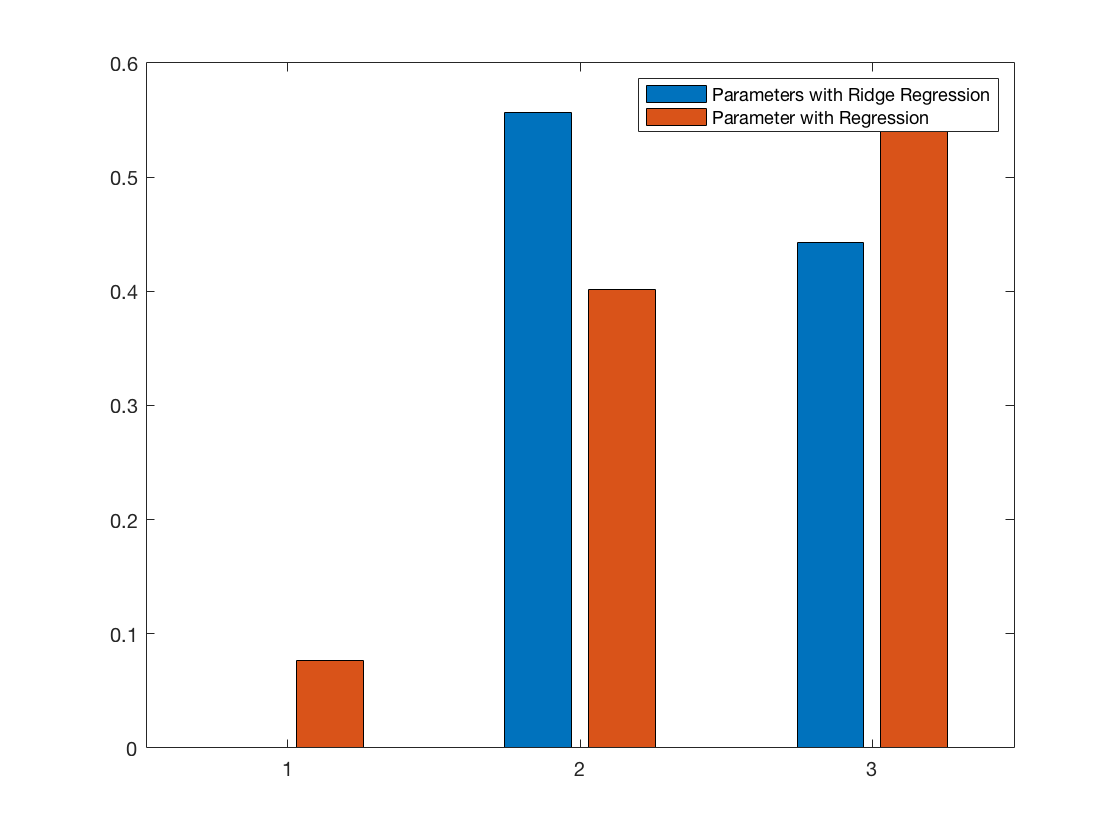

figure;
bar((1:3)', theta_bar_plot);
legend('Parameters with Ridge Regression', 'Parameter with Regression');

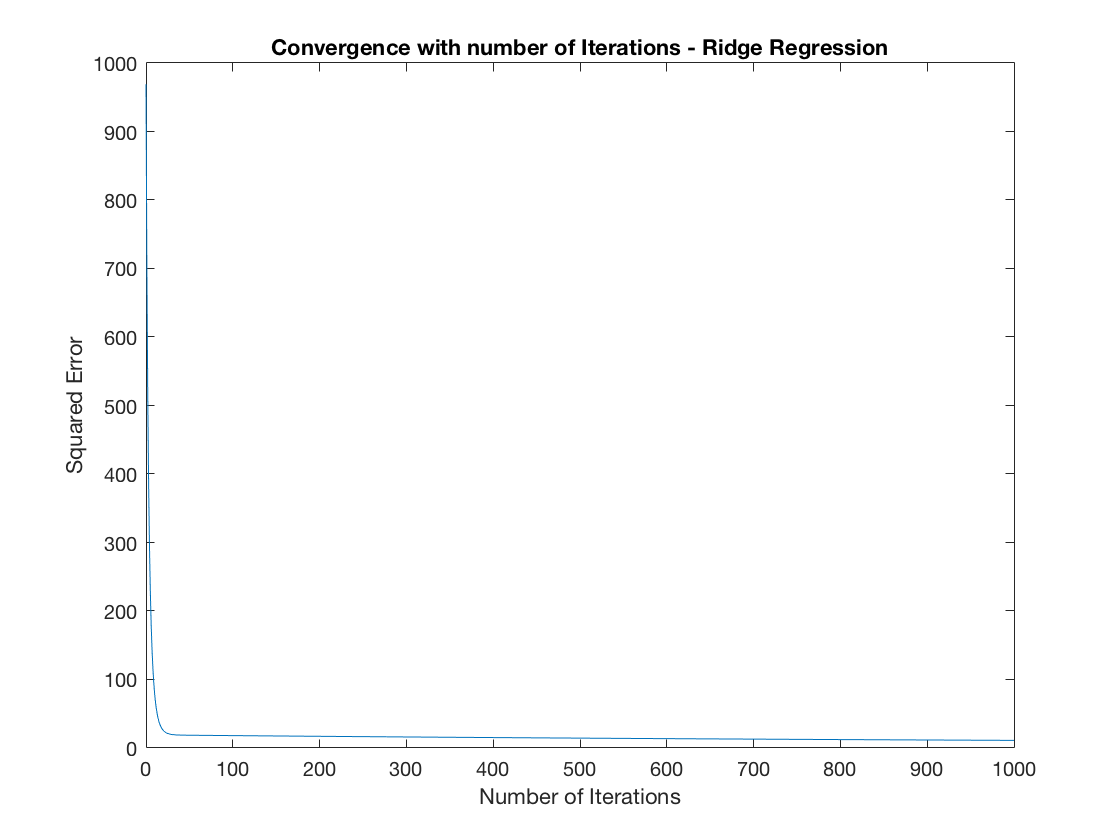

iterations = (0:iters)';
figure;
plot(iterations, err_ridge);
hold on;
xlabel('Number of Iterations');
ylabel('Squared Error');
title('Convergence with number of Iterations - Ridge Regression');